# ECSE 343: Numerical Methods for Engineers - Group Project #1

Due Date: 26th March 2021

Group 8

Student Names: Anas Deis | Yehia Habib | Reza Malekian

Student IDs: 260684605 | 260730649 | 260535177

In engineering applications, you will frequently have occasion to estimate intermediate values between (𝑚+1) data points between an interval [a, b]. A common method used for this purpose is polynomial interpolation. We have seen approximations using a pth order polynomial can be written as, 

 $f\left(x\right)=a_0 +a_1 x+\cdots +a_p x^p$                                                                              (1)

Here our unknowns are the polynomial coefficients, $a_i$’s. The above function can be arranged to form a polynomial matrix function shown below,                         

${\left\lbrack \begin{array}{ccccc}
1 & x_0  & x_0^2  & \cdots  & x_0^p \\
1 & x_1  & x_1^2  & \cdots  & x_1^p \\
1 & x_{2\;}  & x_{2\;}^2  & \cdots \; & x_{2\;}^p \\
\vdots \; & \vdots  & \vdots  & \ddots \; & \vdots \;\\
1 & x_{m-1}  & x_{m-1}^2  & \cdots  & x_{m-1}^p \\
1 & x_m  & x_m^2  & \cdots \; & x_m^p 
\end{array}\right\rbrack }_{\left(m+1\right)\times \left(p+1\right)}$${\left\lbrack \begin{array}{c}
a_0 \\
a_1 \\
a_2 \\
\vdots \\
a_p 
\end{array}\right\rbrack }_{\left(p+1\right)\times 1} ={\left\lbrack \begin{array}{c}
y_0 \\
y_1 \\
y_2 \\
\vdots \\
y_{m-1} \\
y_m 
\end{array}\right\rbrack }_{m\times 1}$, $m\;\ge \;p$                                         (2)

where $x_j$ and $y_j$, $0\le j\le \;m$, are the input and the output data points, respectively. The input data points, $x_j$, lie between in the interval [a, b].

The polynomial function in (1) uses the monomial as basis functions, $\left\lbrace 1,\;x,\;x^2 ,\;\dots ,\;x^p \right\rbrace$, another common approach is to use orthogonal polynomials such as Legendre polynomials. The interpolation formula using an $p^{\textrm{th}}$ order Legendre polynomial can be written as,

 $f\left(x\right)=a_0 \phi_0 \left(x\right)+a_1 \phi_1 \left(x\right)+\cdots +a_p \phi_p \left(x\right)$                                                                              (3)

where $\phi_p \left(x\right)$ represents the degree $p$ Legendre polynomial. The Lagrange polynomials are obtained by applying the Gram-Schmidt orthogonalization process to the monomial basis functions $1,\;x,\;x^2 ,\;\dots ,\;x^p$. The first five Legendre polynomials are shown in Table 1.

Table 1: Table showing the first five Legendre Polynomials.

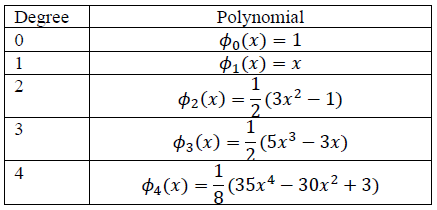

We solve for the coefficients and then we can evaluate function in (1) between the given interval [a, b]. Using (3), we can create a system similar to (2) which can be written as

${\left\lbrack \begin{array}{ccccc}
\phi_0 \left(x_0 \right) & \phi_1 \left(x_0 \right) & \phi_2 \left(x_0 \right) & \cdots  & \phi_p \left(x_0 \right)\\
\phi_0 \left(x_1 \right) & \phi_1 \left(x_1 \right) & \phi_2 \left(x_1 \right) & \cdots  & \phi_p \left(x_1 \right)\\
\phi_0 \left(x_2 \right) & \phi_1 \left(x_2 \right) & \phi_2 \left(x_2 \right) & \cdots \; & \phi_p \left(x_2 \right)\\
\vdots \; & \vdots  & \vdots  & \ddots \; & \vdots \;\\
\phi_0 \left(x_{m-1} \right) & \phi_1 \left(x_{m-1} \right) & \phi_2 \left(x_{m-1} \right) & \cdots  & \phi_p \left(x_{m-1} \right)\\
\phi_0 \left(x_m \right) & \phi_1 \left(x_m \right) & \phi_2 \left(x_m \right) & \cdots \; & \phi_p \left(x_m \right)
\end{array}\right\rbrack }_{\left(m+1\right)\times \left(p+1\right)}$${\left\lbrack \begin{array}{c}
a_0 \\
a_1 \\
a_2 \\
\vdots \\
a_p 
\end{array}\right\rbrack }_{\left(p+1\right)\times 1} ={\left\lbrack \begin{array}{c}
y_0 \\
y_1 \\
y_2 \\
\vdots \\
y_{m-1} \\
y_m 
\end{array}\right\rbrack }_{m\times 1}$, $m\;\ge \;p$                                         (4)

where $x_j$ and $y_j$, $0\le j\le \;m$, are the input and the output data points, respectively. The input data points, $x_j$, lie between in the interval [a, b].

The system in (4) can be solved to compute the coefficients $a_i$’s, then we can interpolate using the function described in (3).

        a)     In this project we are going to interpolate the following function between $\left\lbrack 0,2\pi \right\rbrack$,

$g\left(x\right)=\sin \left(5x\right)+2\cos \left(8x\right)+\sin \left(9x\right)+\sin \left(14x\right)$                                                               (5)

b) The matrices described in (2) and (4) can be ill-conditioned, which can result in erroneous results for the coefficients, $a_i$’s. One possible solution to improve the condition number of the matrices is to scale the input data. The input data, $x_j$ , lying between the interval [a b] can be scaled to values between -1 and 1, using the following formula,

${\hat{x} }_j =\frac{2}{b-a}\left(x_j -\frac{a+b}{2}\right)$                                   (6)

method = 'qr'

deg = 73

data_points = 85

cond_M = 4.1755e+17

RMSE = 0.0042

R2 = 1.0000

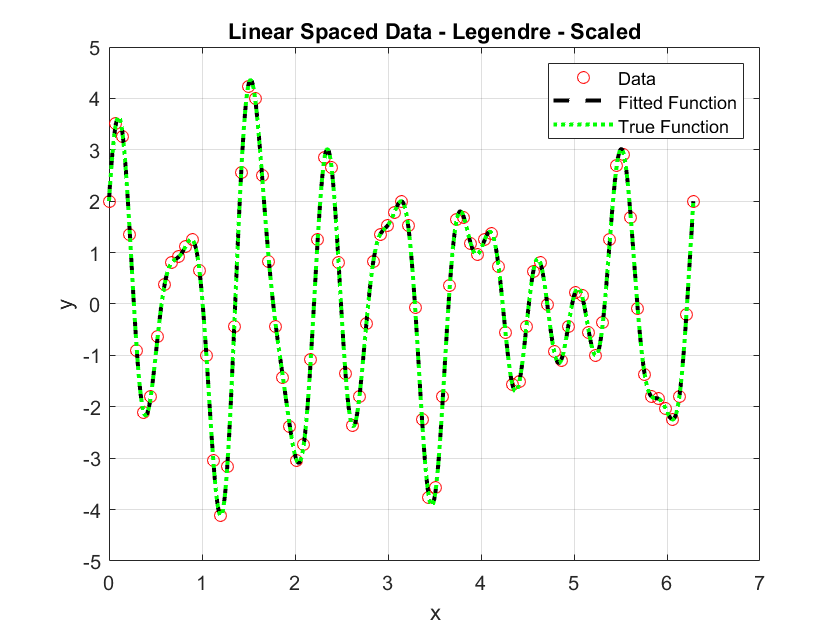

method = 'qr'

deg = 127

data_points = 129

cond_M = 7.6019e+18

RMSE = 0.3323

R2 = 0.9685

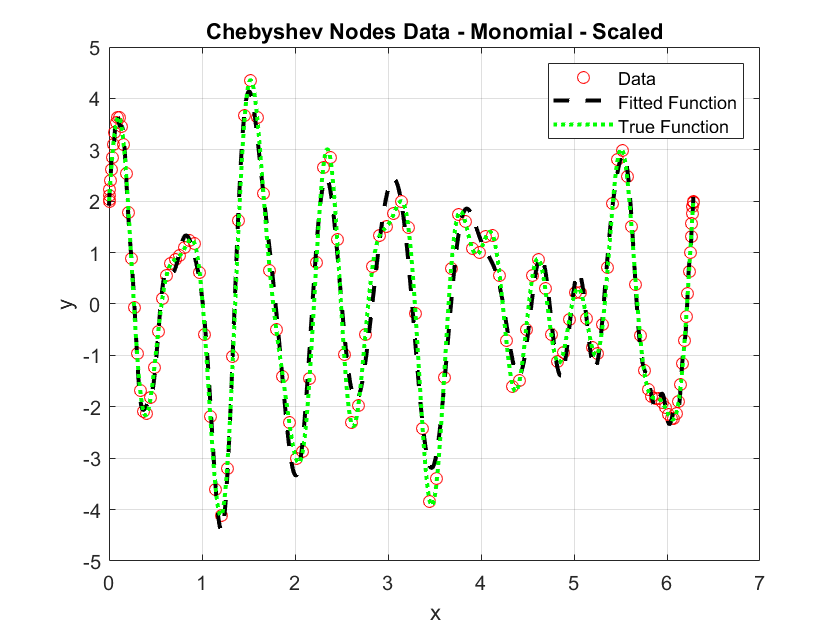

method = 'qr'

deg = 50

data_points = 200

cond_M = 8.3384e+59

RMSE = 1.7760

R2 = 0.1013

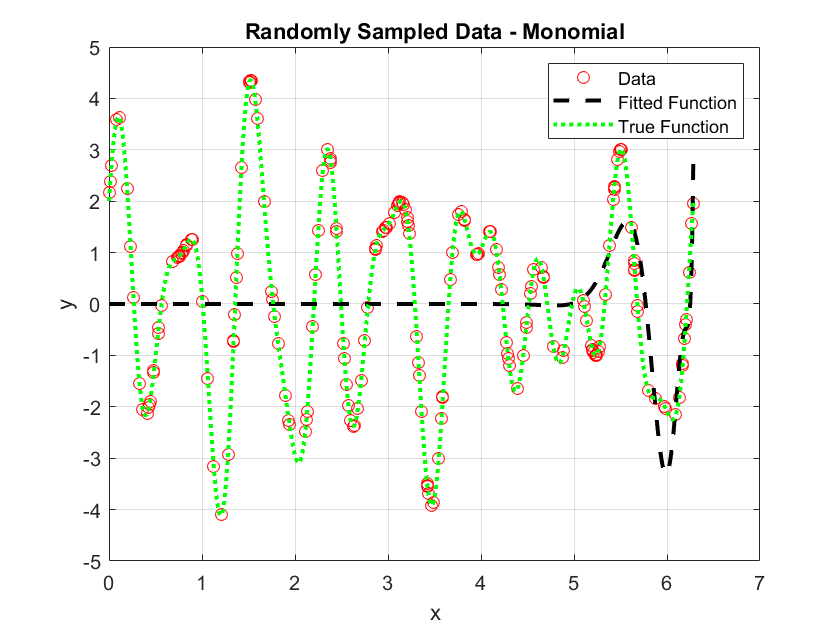

method = 'qr'

deg = 11

data_points = 30

cond_M = 4.6048e+24

RMSE = 1.7041

R2 = 0.1711

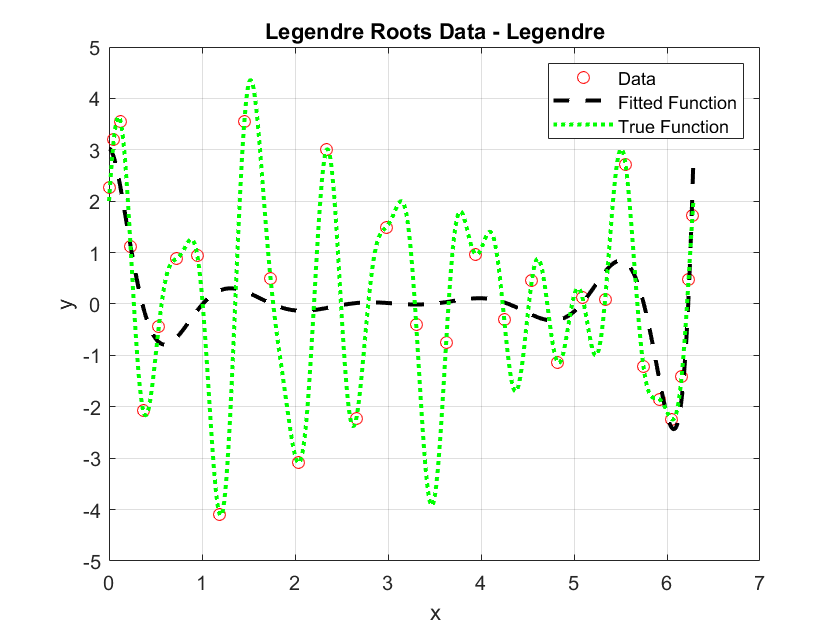

clear all;
global a;
a = 0;
global b;
b = 2*pi;
N = 1000;

% Configuration for all 4 locations of data points (linearly spaced, Chebyshev nodes, randomly sampled, roots of Legendre polynomials)
% tweak degree and data points ('deg', 'num_data')
% select method to compute coefficents ('method'), use 'qr', 'chol', or 'default' as values 
% choose whether to scale by setting 'scale' to true (part b)
% choose whether to use legendre basis by setting 'legendreBasis' to true
% degree must be < data points
% find suitable degree to interpolate the data using as few data points as possible
deg1 = 73; num_data1 = 85; method1 = 'qr'; scale1 = true; legendreBasis1 = true;
deg2 = 127; num_data2 = 128; method2 = 'qr'; scale2 = true; legendreBasis2 = false;
deg3 = 50; num_data3 = 200; method3 = 'qr'; scale3 = false; legendreBasis3 = false;
deg4 = 11; num_data4 = 30; method4 = 'qr'; scale4 = false; legendreBasis4 = true;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% get data points
for val = 1:4
    switch val
        case 1
            [x,y] = Linear_SpacedData(a,b,num_data1);          
            method = method1
            deg = deg1
            scale = scale1;
            legendreBasis = legendreBasis1;
            if legendreBasis
                plot_title = 'Linear Spaced Data - Legendre';  
            else
                plot_title = 'Linear Spaced Data - Monomial';
            end            
        case 2
            [x,y] = Chebyshev_Nodes_Data(b,num_data2);
            method = method2
            deg = deg2  
            scale = scale2;
            legendreBasis = legendreBasis2;
            if legendreBasis
                plot_title = 'Chebyshev Nodes Data - Legendre';  
            else
                plot_title = 'Chebyshev Nodes Data - Monomial';
            end     
        case 3
            [x,y] = RandomlySampled_Data(a,b,num_data3);
            method = method3
            deg = deg3  
            scale = scale3;
            legendreBasis = legendreBasis3;
            if legendreBasis
                plot_title = 'Randomly Sampled Data - Legendre';  
            else
                plot_title = 'Randomly Sampled Data - Monomial';
            end   
        case 4 
            [x,y] = Legendre_Roots_Data(b,num_data4);
            method = method4
            deg = deg4
            scale = scale4;
            legendreBasis = legendreBasis4;
            if legendreBasis
                plot_title = 'Legendre Roots Data - Legendre';  
            else
                plot_title = 'Legendre Roots Data - Monomial';
            end   
    end
    
    % display
    data_points = length(y)
    
    % scale
    x_unscaled = x;
    if scale
        plot_title = strcat(plot_title,' - Scaled');
        x = ScaleData(x);
    end    

    % compute the regression matrix
    if legendreBasis
        M = LegendreMatrix(x,deg);
    else
        M = MonomialMatrix(x,deg);
    end
    
    % condition number of regression matrix
    cond_M = cond(M.'*M)
    
    % compute the coefficients
    switch method
        case 'chol' % Cholensky Decomposition. M.'*M should be positive definite 
            L = chol(M.'*M);
            Z = L.'\(M.'*y);
            coeff = L\Z;
        case 'qr' % QR Decomposition. Computionally intensive, but generally more stable
            [Q,R] = qr(M);
            coeff = (R \ (Q.'*y));
        otherwise % default. Use 'qr' for ill-conditioned M
            coeff = (M.'*M)\(M.'*y);
    end
    
    % check the obtained function
    powers = 0:deg;
    x_new = linspace(a,b,N)';
    f = zeros(length(x_new),1);
    true_function = sin(5*x_new) + 2*cos(8*x_new) + sin(9*x_new) + sin(14*x_new);
    
    if legendreBasis
        if scale
            for I = 1:length(powers)
                f = f + coeff(I)*legendreP(powers(I)*ones(length(x_new),1), ScaleData(x_new));
            end 
        else
            for I = 1:length(powers)
                f = f + coeff(I)*legendreP(powers(I)*ones(length(x_new),1), x_new);
            end 
        end
    else
        for I = 1:length(powers)
            if scale
                f = f + coeff(I)*ScaleData(x_new).^powers(I);
            else
                f = f + coeff(I)*x_new.^powers(I);
            end
        end 
    end

    
    % test error using RMSE and R-squared 
    % lower RMSE is better. 
    % R-squared is between 0 and 1, where 1 is best and 0 is worst.
    % An R-squared of 0.6 reveals that 60% of the data fit the regression model.
    RMSE = norm(true_function - f)/sqrt(length(true_function))
    y1 = true_function-mean(true_function);
    y2 = f-mean(f);
    R2 = (y1.'*y2 / sqrt((y1.'*y1)*(y2.'*y2)))^2
    
    % plot fitted function
    figure
    plot(x_unscaled,y,'ro');
    hold on
    plot(x_new,f,'k--','LineWidth',2)
    plot(x_new,true_function,'g:','LineWidth',2)
    hold off
    xlabel('x')
    ylabel('y')
    legend('Data','Fitted Function','True Function')
    title(plot_title)
    grid on
end

## Appendix

function [x,y] = Linear_SpacedData(a,b,N)
%   This function generates the linearly spaced input data points,x, between
%   the interval [a b]
%   then, provides the output data points by evaluating the true function at those data
%   N is number of data points.
%   x is column vector of input data.
%   y is column vector of output data.

    x = linspace(a,b,N);
    y = sin(5*x) + 2*cos(8*x) + sin(9*x) + sin(14*x);
    
    x = x(:);
    y = y(:);
end
function [x,y] = Chebyshev_Nodes_Data(b,N)
%   This function generates the chebyshev nodes data points, x, between
%   the interval [0 b]
%   then, provides the output data points by evaluating the true function at those data
%   N is number of data points.
%   x is column vector of input data.
%   y is column vector of output data.

    k = 0:N;
    x_cheb = cos(k*pi/N);
    x_cheb = x_cheb(end:-1:1);
    x = b*(x_cheb + 1)/2;
    y = sin(5*x) + 2*cos(8*x) + sin(9*x) + sin(14*x);
    
    x = x(:);
    y = y(:);
end

function [x,y] = Legendre_Roots_Data(b,N)
    % this function provides N data points chosen using Legrendre Roots.
    % then, provides the output data points by evaluating the true function at those data
    % N is number of data points.
    % x is column vector of input data.
    % y is column vector of output data.
    
    syms xp
    x = vpasolve(legendreP(N,xp) == 0);
    x = double(x);
    x = b*(x + 1)/2;
    y = sin(5*x) + 2*cos(8*x) + sin(9*x) + sin(14*x);
    
    x = x(:);
    y = y(:);
end

function [x,y] = RandomlySampled_Data(a,b,N)
%   this function provides N data points chossen using Random Sampling between interval [a b].
%   then, provides the output data points by evaluating the true function at those data
%   N is number of data points.
%   x is column vector of input data.
%   y is column vector of output data.

    x = sort(unifrnd(a,b, N,1));
    y = sin(5*x) + 2*cos(8*x) + sin(9*x) + sin(14*x);
    
    x = x(:);
    y = y(:);
end

function M = MonomialMatrix(x,n)
    % write your code here
    % n is the degree of the polynomial
    % x is the vector of input data    
    x = x(:);
    M = ones(length(x),n+1);
    for I = 0:n
       M(:,I+1) = x.^I;
    end
end

function M = LegendreMatrix(x,n)
    % write your code here
    % n is the degree of the polynomila
    % x is the vector of input data  
    x = x(:);
    N = 0:n;
    N = N(ones(1,length(x)),:);
    x = x(:,ones(1,n+1));
    M = legendreP(N,x);
end

function xs = ScaleData(input)
    % input is the input data
    global a;
    global b;

    xs = (2/(b-a))*(input - (a+b)/2);
end